# Unit Tests D Tree

## Intro

This 'unit test' document was used to try and find out why my implementation was returning different results than the built in matlab tree. It turns out that the implementation that Matlab uses is alot more complex than the implementation taught in Jhon's lectures (not that that is a bad thing!!). In order to optimise the performance and construction of the tree Matlab does not evaluate every observation when trying to perform a split. This can be seen in the data below. 

Here we see two trees being constructed. The first splits however are different. The split that my model makes is more pure than that of matlabs. Below is proof.

rng(0);
[train_examples,~,train_labels,~] = prepare_dataset('biopsies.csv',1,0.6);

Sample of data:

ans = 10×31 cell array
    {'diagnosis'}    {'radius_mean'}    {'texture_mean'}    {'perimeter_mean'}    {'area_mean'}    {'smoothness_mean'}    {'compactness_mean'}    {'concavity_mean'}    {'concave points_mean'}    {'symmetry_mean'}    {'fractal_dimension_mean'}    {'radius_se'}    {'texture_se'}    {'perimeter_se'}    {'area_se'}    {'smoothness_se'}    {'compactness_se'}    {'concavity_se'}    {'concave points_se'}    {'symmetry_se'}    {'fractal_dimension_se'}    {'radius_worst'}    {'texture_worst'}    {'perimeter_worst'}    {'area_worst'}    {'smoothness_worst'}    {'compactness_worst'}    {'concavity_worst'}    {'concave points_worst'}    {'symmetry_worst'}    {'fractal_dimension_worst'}
    {'Benign'   }    {[    -0.1667]}    {[     -1.1462]}    {[       -0.1856]}    {[  -0.2517]}    {[         0.1017]}    {[         -0.4365]}    {[       -0.2780]}    {[            -0.0286]}    {[       0.2677]}    {[               -0.7277]}    {[  -0.4878]}    {[   -0.7763]}    {[     -0.399

test_examples size:	 228 30
test_labels size:	 228 1
train_examples size:	 341 30
train_labels size:	 341 1



% matlabs model
sd = fitctree(train_examples, train_labels,'MergeLeaves', 'off','Prune','off', 'MinParentSize',1)

sd =   ClassificationTree
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [Benign    Malignant]
           ScoreTransform: 'none'
          NumObservations: 341


  Properties, Methods


% my model
md = my_fitctree(train_examples, train_labels,'MinParentSize', 1)

md =   my_ClassificationTree with properties:

    CutPredictorIndex: [25×1 double]
             CutPoint: [25×1 double]
             Children: [25×2 double]
     ClassProbability: [25×2 double]
            NodeClass: [25×1 categorical]
             NodeRisk: [25×1 double]
             NumNodes: 25
        MinParentSize: 1
         MaxNumSplits: 340
                    X: [341×30 double]
                    Y: [341×1 categorical]
           ClassNames: [2×1 categorical]
      NumObservations: 341
      PredictorIndexs: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30]



% different cut points on first node.
[md.CutPoint(1) sd.CutPoint(1)]

ans =     0.1752    0.1648


[md.CutPredictorIndex(1) sd.CutPredictorIndex(1)]

ans =     23    23



% purity of first cut
% Matlab purity
sum(sd.NodeRisk(2:3))

ans = 0.1406


% My purity
sum(md.NodeRisk(2:3))

ans = 0.1403

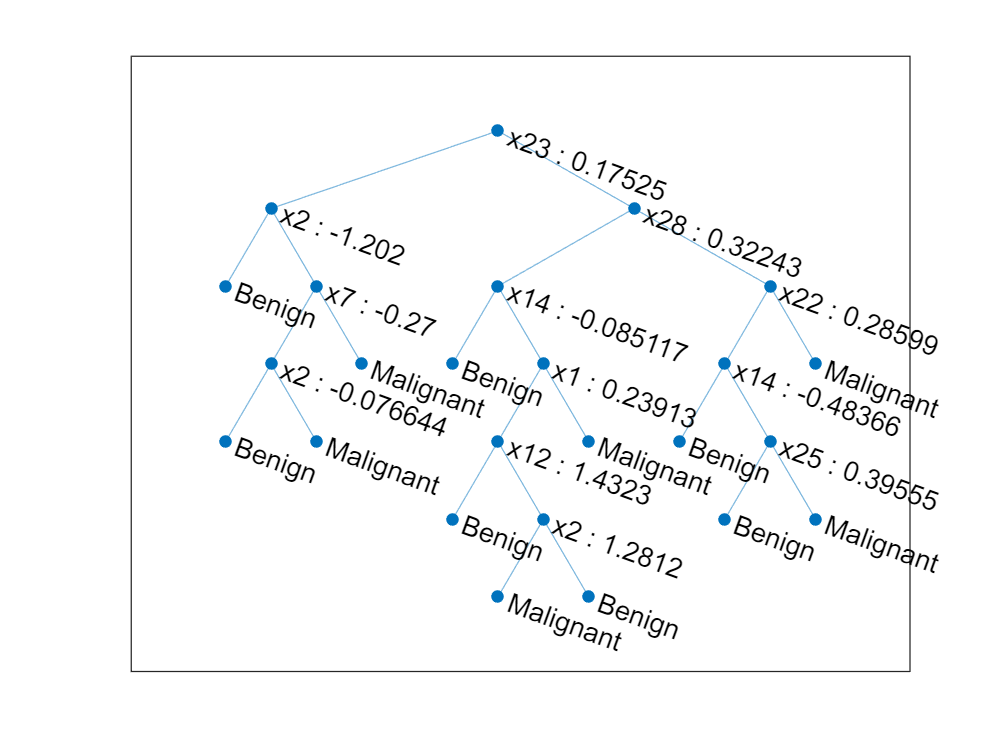


% Visual comparison
md.view

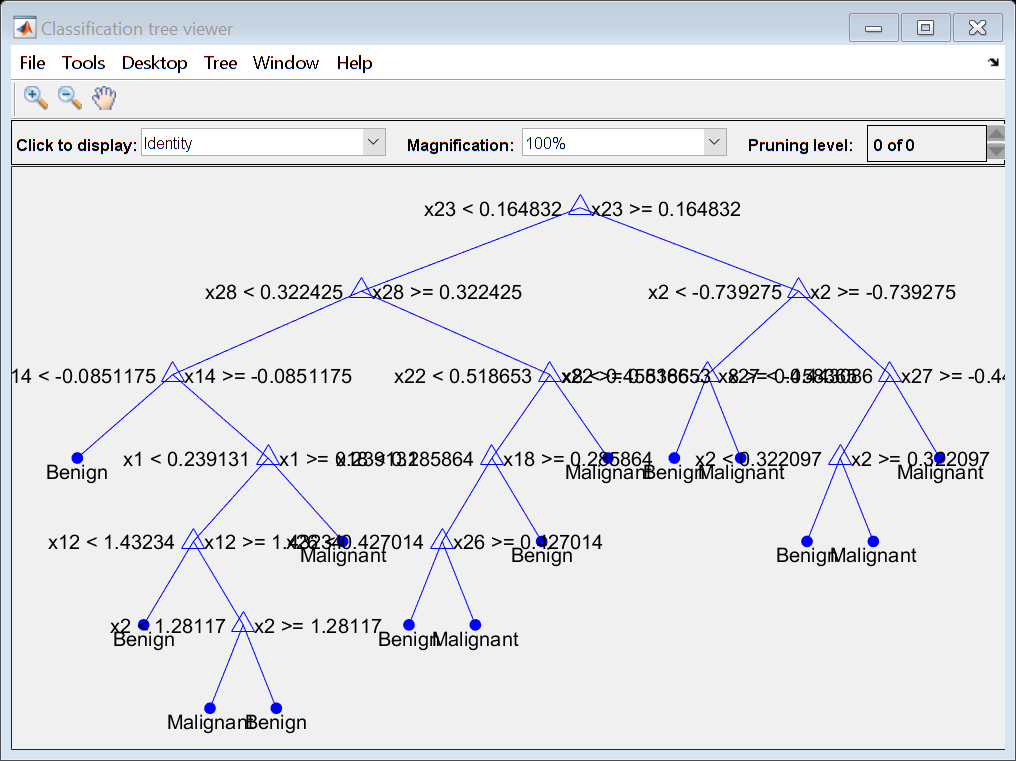

sd.view('Mode','graph')

Even though my node risk is less by 0.0003, it still shows that matlab does not look for the best split but has an optimisation process.

With that said my trees and matlabs trees will sometimes look different however this does not show my lack of ability to follow Jhon's implementation, rather a difference in the implementation taught and the one used in Matlab.

## Initialisation

Please try for yourself changing the file name in `prepare_dataset. `You will also have to change the second argument that corrisponds to the target label. For sepal.csv it is 3, biopsies it is 1 etc.. 

When you have selected the file press` Run to End` to avoid running the previous section again. This unit test compares the structure of my Tree to Matlabs. If the two trees have different numbers of children none of the tests will run however. In this case try using a different amount of splits, parent size until they do have the same number of children.

rng(0);

% second argument holds the index, read the doc or call help for more info
[train_examples,test_examples,train_labels,test_labels] = prepare_dataset('sepal.csv',3,0.6);

Sample of data:

ans = 10×3 cell array
    {'sepal_length'}    {'sepal_width'}    {'species'}
    {[      5.1000]}    {[     3.5000]}    {'setosa' }
    {[      4.9000]}    {[          3]}    {'setosa' }
    {[      4.7000]}    {[     3.2000]}    {'setosa' }
    {[      4.6000]}    {[     3.1000]}    {'setosa' }
    {[           5]}    {[     3.6000]}    {'setosa' }
    {[      5.4000]}    {[     3.9000]}    {'setosa' }
    {[      4.6000]}    {[     3.4000]}    {'setosa' }
    {[           5]}    {[     3.4000]}    {'setosa' }
    {[      4.4000]}    {[     2.9000]}    {'setosa' }


test_examples size:	 60 2
test_labels size:	 60 1
train_examples size:	 90 2
train_labels size:	 90 1



splits = 1000;

sd = fitctree(train_examples, train_labels,'MergeLeaves', 'off', ...
    'Prune','off', 'MinParentSize',1, 'MaxNumSplits',splits)

sd =   ClassificationTree
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [setosa    versicolor    virginica]
           ScoreTransform: 'none'
          NumObservations: 90


  Properties, Methods


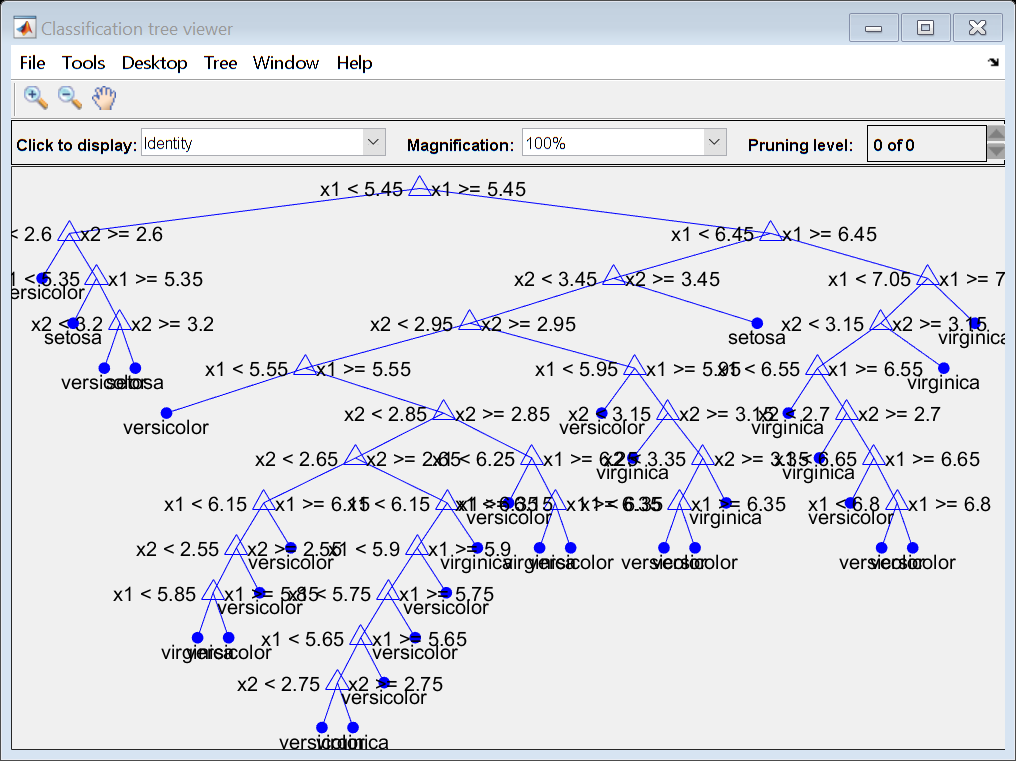

sd.view('Mode', 'graph');

md = my_fitctree(train_examples, train_labels,'MinParentSize', 1, ...
    'MaxNumSplits',splits)

md =   my_ClassificationTree with properties:

    CutPredictorIndex: [61×1 double]
             CutPoint: [61×1 double]
             Children: [61×2 double]
     ClassProbability: [61×3 double]
            NodeClass: [61×1 categorical]
             NodeRisk: [61×1 double]
             NumNodes: 61
        MinParentSize: 1
         MaxNumSplits: 1000
                    X: [90×2 double]
                    Y: [90×1 categorical]
           ClassNames: [3×1 categorical]
      NumObservations: 90
      PredictorIndexs: [1 2]


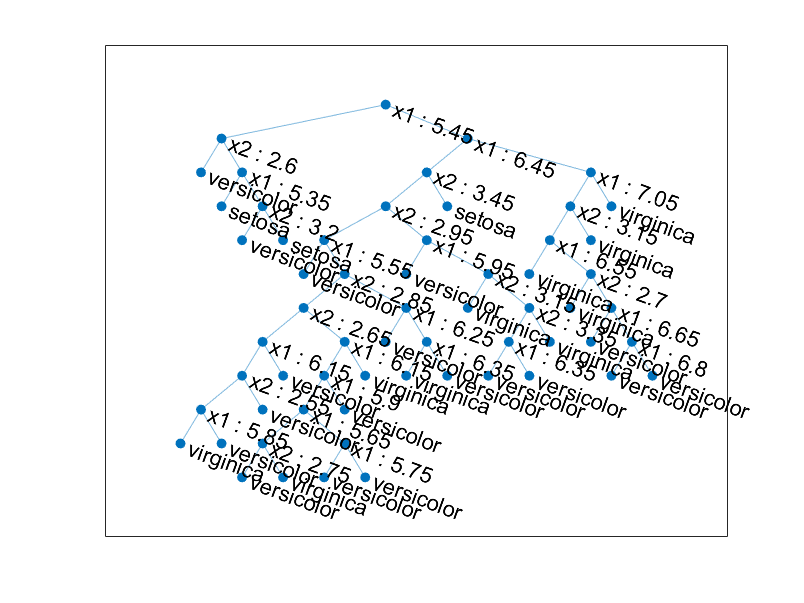

md.view()

## Make same amount of children

i = height(sd.Children) == height(md.Children);
if i == 1
    fprintf("Same amount of children = %i", height(md.Children));
else
    fprintf("Differnet amount of children\nsd: %i\tmd:%i",height(sd.Children),height(md.Children));
end

Same amount of children = 61

## Children are the same

% % of same results
i = sum(sd.Children(:) == md.Children(:))/height(md.Children(:)) .*100;
fprintf("Children are %f%% identical",i);

Children are 96.721311% identical


% find indexs of mismatched results
if i ~= 100
    i = sd.Children(:,:) ~= md.Children(:,:);
    find(i)
    [sd.Children md.Children]
    
    [sd.Children(i(:,1),:) md.Children(i(:,1),:)]
end

ans =     57
    58
   118
   119


ans =      2     3     2     3
     4     5     4     5
     6     7     6     7
     0     0     0     0
     8     9     8     9
    10    11    10    11
    12    13    12    13
     0     0     0     0
    14    15    14    15
    16    17    16    17


ans =      0     0    60    61
    60    61     0     0


## Node class are the same

i = sum(sd.NodeClass == md.NodeClass)/height(md.NodeClass) .*100;
fprintf("Node Classes are %f%% identical",i);

Node Classes are 96.721311% identical

if i ~= 100
    i = sd.NodeClass ~= md.NodeClass;
    [sd.NodeClass md.NodeClass]
    find(i)
    [sd.NodeClass(i), md.NodeClass(i)]
end

ans = 61×2 categorical array
     setosa          setosa     
     setosa          setosa     
     virginica       virginica  
     versicolor      versicolor 
     setosa          setosa     
     versicolor      versicolor 
     virginica       virginica  
     setosa          setosa     
     setosa          setosa     
     versicolor      versicolor 
     setosa          setosa     
     virginica       virginica  
     virginica       virginica  
     versicolor      versicolor 
     setosa          setosa     
     versicolor      versicolor 
     virginica       virginica  
     versicolor      versicolor 
     virginica       virginica  
     versicolor      versicolor 
     versicolor      versicolor 
     versicolor      versicolor 
     virginica       virginica  
     virginica       virginica  
     versicolor      versicolor 
     versicolor      versicolor 
     versicolor      versicolor 
     virginica       virginica  
     versicolor      versicolor 
     virginica

ans =     59
    61


ans = 2×2 categorical array
     versicolor      virginica  
     virginica       versicolor 


## Cut points are the same

i = sd.CutPoint ~= md.CutPoint & ~(isnan(sd.CutPoint) & isnan(md.CutPoint));
f = (height(md.CutPoint) - sum(i))/height(md.CutPoint) .*100;
fprintf("CutPoints are %f%% identical",f);

CutPoints are 93.442623% identical

if f ~= 100
    [sd.CutPoint md.CutPoint]
    [find(i) sd.CutPoint(i) md.CutPoint(i)]
end

ans =     5.4500    5.4500
    2.6000    2.6000
    6.4500    6.4500
       NaN       NaN
    5.3500    5.3500
    3.4500    3.4500
    7.0500    7.0500
       NaN       NaN
    3.2000    3.2000
    2.9500    2.9500


ans =    52.0000    5.7500    5.6500
   56.0000    5.6500    2.7500
   57.0000       NaN    5.7500
   58.0000    2.7500       NaN


## Node risk are the same

% have to do wierd shit cause floats are stored as IEE745, wierd stuff happenes 
i = round(sd.NodeRisk(:)*1e5)/1e5 ~= round(md.NodeRisk(:)*1e5)/1e5;
f = (height(sd.NodeRisk) - sum(i))/height(sd.NodeRisk)*100;
fprintf("NodeRisks are %f%% identical",f);

NodeRisks are 93.442623% identical


if f ~= 100
    [sd.NodeRisk md.NodeRisk]
    [find(i) sd.NodeRisk(i) md.NodeRisk(i)]
end

ans =     0.6620    0.6620
    0.0610    0.0610
    0.3358    0.3358
         0         0
    0.0215    0.0215
    0.2076    0.2076
    0.0711    0.0711
         0         0
    0.0148    0.0148
    0.1604    0.1604


ans =    56.0000    0.0148    0.0111
   57.0000    0.0111    0.0148
   58.0000    0.0111         0
   61.0000         0    0.0111


## Cut Point Index are the same

% have to do wierd shit cause floats are stored as IEE745, wierd stuff happenes 
i = sd.CutPredictorIndex ~= md.CutPredictorIndex;
f = (height(sd.CutPredictorIndex) - sum(i))/height(sd.CutPredictorIndex)*100;
fprintf("CutPredictorIndex are %f%% identical",f);

CutPredictorIndex are 95.081967% identical


if f ~= 100
    [sd.CutPredictorIndex md.CutPredictorIndex]
    [find(i) sd.CutPredictorIndex(i) md.CutPredictorIndex(i)]
end

ans =      1     1
     2     2
     1     1
     0     0
     1     1
     2     2
     1     1
     0     0
     2     2
     2     2


ans =     56     1     2
    57     0     1
    58     2     0


## Predictions are the same

% predict values
p_sd = sd.predict(test_examples);
p_md = md.predict(test_examples);

% compare
f = (sum(p_sd == p_md)/height(p_sd)) * 100;
fprintf("Predictions are %f%% identical",f);

Predictions are 100.000000% identical


i = p_sd ~= p_md;
if sum(i) ~= 0
    [sd.CutPredictorIndex md.CutPredictorIndex]
    [find(i) sd.CutPredictorIndex(i) md.CutPredictorIndex(i)]
    
    % find accuracy
    sum(p_sd == test_labels)/height(test_labels)
    sum(p_md == test_labels)/height(test_labels)
end
